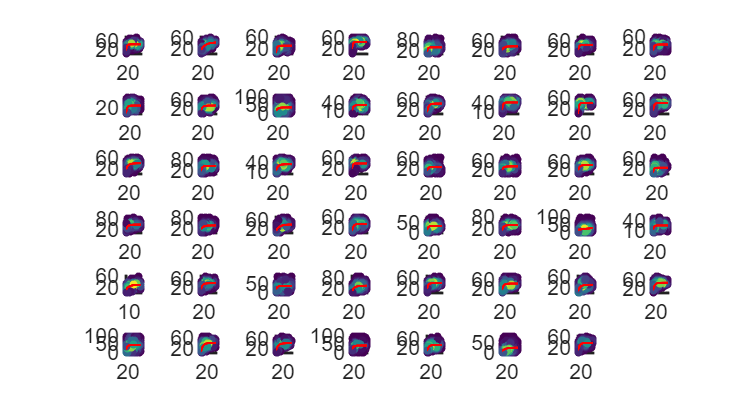

clc;clear;close all; addpath z_toolbox;
clc; clear; addpath z_toolbox;
load(fullfile('step4_IEDtw_TD-6d0_IT-100ms_fitting', ...
    'op5_IEDtw_ED-vs-delay_rate-vs-delay_fitting.mat'), 'ED_delay_fit');
figure('Units', 'centimeters', 'Position', [5, 5, 36, 20]);
for nS = 1:47
    ED = ED_delay_fit(nS).ED;
    IEDtwD = ED_delay_fit(nS).delay;
    Curve = ED_delay_fit(nS).curve_exp;
    subplot(6, 8, nS);
    f_densityScatter(ED, IEDtwD, 2); hold on;
    plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
    xlim([min(ED), max(ED)]); ylim([min(IEDtwD), max(IEDtwD)]);
    set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
end